
8793

ans = 8793

IAE = 265.0857				P = 77.4287		I = 269.648		D = 13.1136
IAE = 219.5042				P = 215.4546		I = 648.6869		D = 16.1113
IAE = 238.1901				P = 198.9175		I = 548.9058		D = 59.0499
IAE = 169.6581				P = 85.4627		I = 86.5655		D = 61.4477
IAE = 265.695				P = 68.5595		I = 234.9526		D = 14.2848
IAE = 198.3486				P = 254.179		I = 752.0351		D = 56.5672
IAE = 29.1786				P = 149.4543		I = 994.4278		D = 1.5948
IAE = 218.5926				P = 254.5469		I = 127.3265		D = 46.9823
IAE = 282.3457				P = 186.079		I = 136.8245		D = 32.417
IAE = 100.0524				P = 22.3361		I = 672.9654		D = 50.5636
IAE = 72.7011				P = 108.9622		I = 731.4488		D = 9.262
IAE = 229.1383				P = 79.6947		I = 357.7418		D = 27.0653
IAE = 278.7143				P = 209.5188		I = 253.1531		D = 39.8351
IAE = 39.3986				P = 246.2746		I = 646.093		D = 6.4642
IAE = 202.8867				P = 97.6252		I = 939.6271		D = 13.7572
IAE = 273.3914				P = 253.8064		I = 223.3486		D = 63.332
IAE = 119.0377				P = 73.2074		I = 649.6765		D = 61.4972
IAE = 204.0721				P = 111.4701		I = 

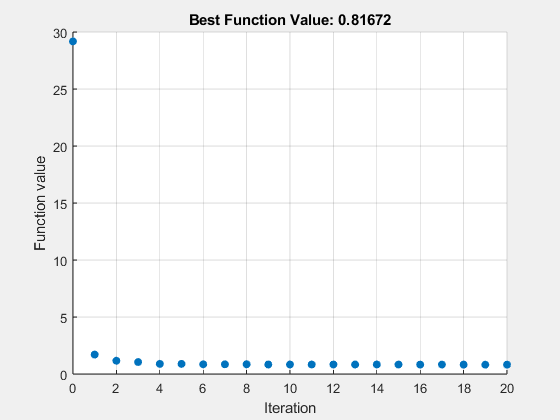

% Set nondefault solver options
options2 = optimoptions("particleswarm","InertiaRange",Inertia_range,...
    "SelfAdjustmentWeight",2.8,"SocialAdjustmentWeight",1.3,"MaxIterations",...
    20,"MaxStallIterations",10,"Display","iter","PlotFcn","pswplotbestf");

% Solve
[sol,obj] = particleswarm(@tunning,numvar,lower_bounds,...
    upper_bounds,options2);


% Clear variables
clearvars options2